# Mohammadreza Arani

## Convex Optimization

## 810100511

## Project 4:

## Optimizing the sequence of commitments in an alternative investment

clear ; clc ; close all;

% Initialization:

% Part (a):


T = 40;  % Periods
r = 0.04; % the per-period return

gamma_call = 0.23;
gamma_dist = 0.15; % call and distribution intensities

c_max = 4; 
p_max = 3; 

B = 85; % total budget
n_des = 15; % given positive target NAV
lambda = 5;

alpha = 1 + r - gamma_dist;
beta = 1 - gamma_call;

% Your job is to choose the sequence of commitments c = (c1, . . . , cT )
%  ct ≤ cmax and pt ≤ pmax  //// cmax > 0 and pmax > 0
% total budget B > 0 
% 1T c ≤ B

*** Critical Quantities:***

    • *c**t **≥ *0 denotes the amount that the investor commits in period *t*.

    • *p**t **≥ *0 denotes the amount that the investor pays in to the investment in response to capital calls in period  *t*.

    • *d**t **≥ *0 denotes the amount that the investor receives in distributions from the investment in period  *t*.

    • *n**t **≥ *0 denotes the net asset value (NAV) of the investment in period *t*.

    • *u**t **≥ *0 denotes the total amount of uncalled commitments, i.e., the diﬀerence between the total so far committed and the total so far that has been called (and paid into the investment)

  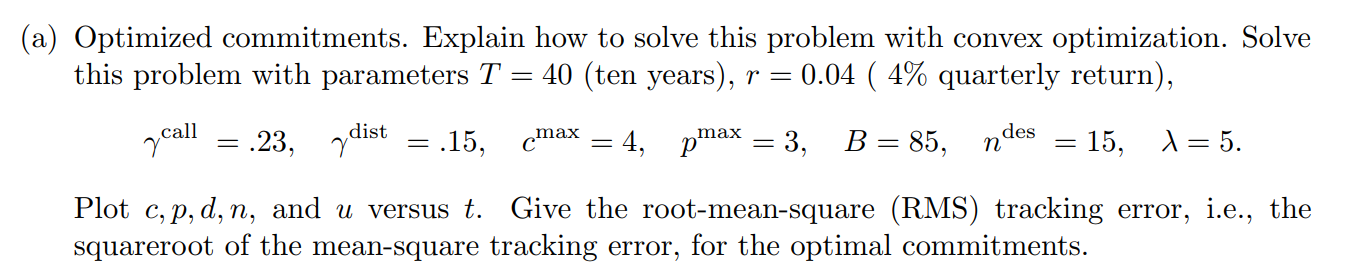

Above we saw definitions and criterias for this problem:

    The objective function is:

        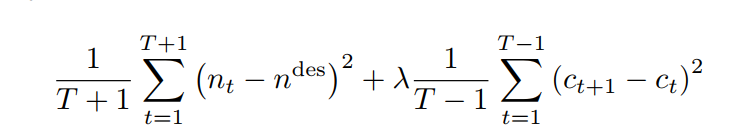

with given dynamics of parameters:

    

There are so many constraints!

==> To simplify the dynamics and unify the criterias we can rewrite:


$$u_{t+1} =u_t -\gamma^{\textrm{call}} u_t +c_t =\beta u_t +c_t$$



$$n_{t+1} =\left(1+r\right)n_t +\gamma^{\textrm{call}} u_t -\gamma^{\textrm{dist}} n_t =\alpha \;n_t +\gamma^{\textrm{call}} u_t$$



$$\begin{array}{l}
\\
\beta =1-\gamma^{\textrm{call}} \\
\alpha =1+r-\gamma^{\textrm{dist}} \\
\;\\
u_1 =0\Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;|\;n_1 =0\\
u_2 =c_1 \Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;|\;n_2 =0\\
u_3 =c_2 +\beta \;c_1 \Rightarrow \;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;|n}_3 =\gamma^{\textrm{call}} u_2 \\
u_4 =c_3 +\beta c_2 +\beta^2 c_{1\;} \Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;|n_4 =\gamma^{\textrm{call}} \left(u_3 +\alpha \;u_2 \right)\\
u_5 =c_4 +\beta c_3 +\beta^2 c_2 +\beta^3 c_1 \Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;|n_5 =\gamma^{\textrm{call}} \left(u_4 +\alpha \;u_3 +\alpha^2 \;u_2 \right)\\
\ldotp \\
\ldotp \\
\ldotp \\
u_{t+1} =c_t \;\;\;+\;\;\beta c_{t-1} \;\;+\;\ldotp \ldotp \ldotp \;+{\;\beta }^{t-2\;\;} c_{2\;} +\;\;\beta^{t-1} c_{1\;\;\;\;\;\;\;} \;\;\;\;\;\;\;|\;n_{t+1} =\gamma^{\textrm{call}} \left(u_t +\alpha u_{t-1} +\;\ldotp \ldotp \ldotp \;+\alpha^{t-2} u_2 \right)
\end{array}$$


Above we did simplified the relationships and now we can use them:

    min OBjective =  $\min \;\frac{1}{T+1}\sum_{t=1}^{T+1} {\left(n_t -n_{\textrm{des}} \right)}^2 +\frac{\lambda }{T-1}\sum_{t=1}^{T-1} {\left(c_{t+1} -c_t \right)}^2$

    S.T.

            
$$\;\;\;\;\;n_{t+1} =\gamma^{\textrm{call}} \left\lbrack c_{t-1} +\left(\beta +\alpha \;\right)c_{t-2} +\left(\beta {\;}^2 +\alpha \;\beta +\alpha^2 \right)c_{t-3} +\;\ldotp \ldotp \ldotp +\left(\beta {\;}^{t-2} +\beta {\;}^{t-3} \alpha +\ldotp \ldotp \ldotp +\beta \;\alpha {\;}^{t-3} +\alpha^{t-2} \right)c_1 \right\rbrack$$



$$\textrm{for}\;t=2,\ldotp \ldotp \ldotp ,T$$


                $n_1 =n_2 =0$    : net asset value   

                ${0\le u}_t \le \frac{p_{\max } }{\gamma^{\textrm{call}} }\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T$  : uncalled commitments  

                $0\le c_t \le c_{\max } \;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T$   : Positive Contribution with a bound!

                
$$n_t \ge 0\;\;\;t=3,\ldotp \ldotp \ldotp ,T$$


               $1^T c\le B$  : Must not exceed total Budget! 

% Our objective happens to be Quadratic! ==> Convex when the Matrix P is PD
% ==> Convex
 %% Solve Part (a) ::: CVX:
cvx_begin
    variables c(T);
        u(2) = c(1); % Values for t =1 ;
        % Dynamics of Parameters: 
        for t = 2 : T
            u(t+1) = (1-gamma_call).^(0:t-1)*c(t:-1:1);
            for i = 1 : t-1
                coeff(i) = sum(alpha.^(0:i-1) .* beta.^(i-1:-1:0));
            end
            n(t+1) = gamma_call*( coeff *c(t-1:-1:1));
        end

    My_Objective = 1/(T+1) * sum((n-n_des).^2) + lambda/(T-1) * sum( (c(2:end)-c(1:end-1)) .^2 );
    minimize( My_Objective );
    subject to


        u(:) >= 0;
        u(:) <= p_max/gamma_call;
        c(:) >= 0;
        c(:) <= c_max;

        n(1) == 0;
        n(2) == 0;
        n(:) >= 0;

        ones(1, T)*c <= B; % The budget
cvx_end 

 
Calling SDPT3 4.0: 435 variables, 118 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 118
 dim. of sdp    var  = 156,   num. of sdp  blk  = 78
 dim. of linear var  = 201
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.4e+02|9.4e+00|4.2e+05| 1.325268e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.835|0.863|5.6e+01|1.3e+00|7.1e+04| 1.619579e+04 -8.711582e+01| 0:0:00| chol  1  1 
 2|0.777|0.826|1.2e+01|2.3e-01|3.1e+04| 1.741752e+04 -4.578164e+02| 0:0:00| chol  1  1 
 3|0.996|1.000|4.9e-02|1.0e-04|9

p(1:T) = gamma_call*u(1:T);
d(1:T) = gamma_dist*n(1:T);

## Plot:

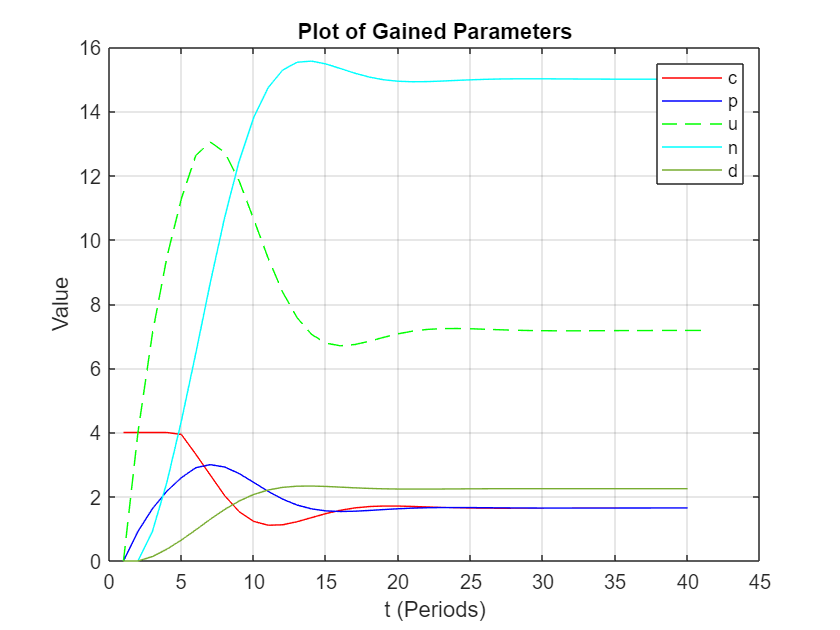


figure()
plot(c,'r') % Our parameter --> Commitments
hold on
plot(p,'b')
plot(u,'g--')
plot(n,'c')
plot(d)
xlabel('t (Periods)')
ylabel('Value');
legend('c', 'p',  'u','n','d')
grid on
title("Plot of Gained Parameters")

% Calculate The Tracking Error:
disp("Tracking error : " )

Tracking error : 


disp(  1/(T+1) * sum((n-n_des).^2))

   25.8462



disp("Objective Value after Optimization : " )

Objective Value after Optimization : 


disp( My_Objective)

   26.0552



## Part (b) : Constant commitment based on steady-state.  

% ct = css --> Constant!

c_ss = (gamma_dist-r)*n_des*ones(T,1); % Given Relation!
% Do the dynamics of eqs:
u_ss(2:T+1) = (gamma_dist-r)*n_des/(1-beta)*(1-beta.^(1:T));
n_ss = zeros(T+1,1);
for t = 2 : T
    coeff_ss = [];
    for i = 1 : t-1
        coeff_ss(i) = sum(alpha.^(0:i-1) .* beta.^(i-1:-1:0));
    end
    n_ss(t+1) = gamma_call*( coeff_ss *c_ss(t-1:-1:1));
end
p_ss(1:T) = gamma_call*u_ss(1:T);
d_ss(1:T) = gamma_dist*n_ss(1:T);

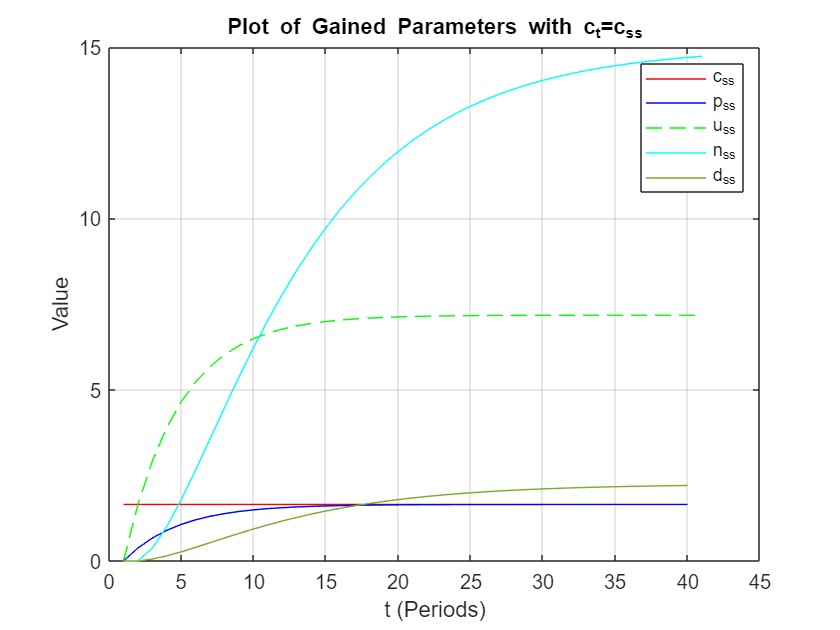

figure()
plot(c_ss,'r') % Our parameter --> Commitments
hold on
plot(p_ss,'b')
plot(u_ss,'g--')
plot(n_ss,'c')
plot(d_ss)
xlabel('t (Periods)')
ylabel('Value');
legend('c_{ss}', 'p_{ss}',  'u_{ss}','n_{ss}','d_{ss}')
grid on
title("Plot of Gained Parameters with c_t=c_{ss}")

% Calculate The Tracking Error:
disp("Tracking error for c_{ss} : " )

Tracking error for c_{ss} : 


disp(  1/(T+1) * sum((n_ss-n_des).^2))

   47.0143



disp("Steady state Objective for c_{ss} value: " )

Steady state Objective for c_{ss} value: 


disp(  (1/(T+1) * sum((n_ss-n_des).^2) + lambda/(T-1) * sum( (c_ss(2:end)-c_ss(1:end-1)) .^2 )) )

   47.0143



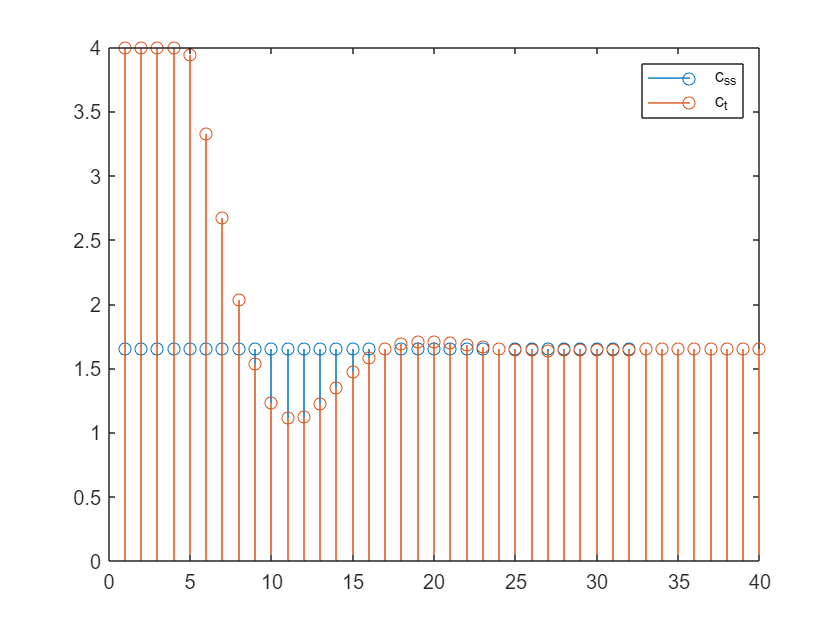


figure()
stem(c_ss)
hold on
stem(c)
legend('c_{ss}','c_t') % we can see the convergence!

We can see the convergence of ct to c_constant!

The regulatory term is zeros for constant commitments! ==> tracking error rises! [because we are not following dynamics!]